# Problema 2

% PB1
function [noduri, coeficienti] = gauss_legendre(n)
    alpha = zeros(n, 1);
    beta = zeros(n-1, 1);
    for k = 1:n-1
        beta(k) = 1 / sqrt(4 - 1/(k^2));
    end
    J = diag(alpha) + diag(beta, 1) + diag(beta, -1);
    [V, D] = eig(J);
    noduri = diag(D);  
    [noduri, ord] = sort(noduri);
    V = V(:, ord);
    coeficienti = 2 * V(1,:).^2;  
end

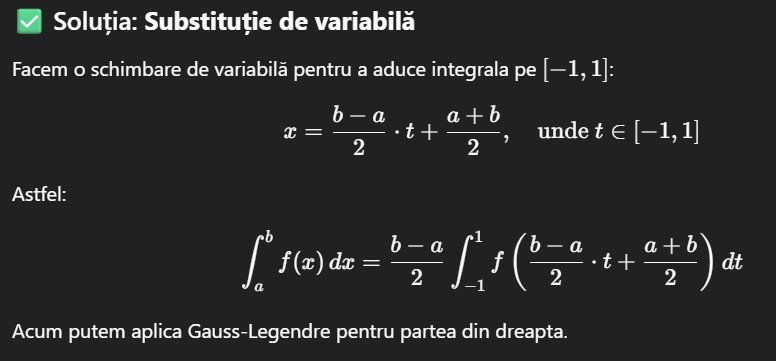

function [I, n] = integrare_legendre_adaptiv(f, a, b, eps)
% Input:
%   f   - functia de integrat
%   a   - capat stanga
%   b   - capat dreapta
%   eps - precizia dorita
%
% Output:
%   I - valoarea aproximata a integralei
%   n - numarul de noduri necesare

    n = 2;
    [x, A] = gauss_legendre(n);

    % Transformare noduri in intervalul [a, b]
    % Se face schimb de variabila deoarece ca sa folosim acest mod de
    % calcul integrala trebuie sa fie definita pe [-1,1] nu pe [a,b]
    t = ((b - a)/2) * x + (a + b)/2;
    I_prev = ((b - a)/2) * sum(A .* f(t(:))');

    while true
        n = n + 1;
        [x, A] = gauss_legendre(n);
        t = ((b - a)/2) * x + (a + b)/2;
        I_curr = ((b - a)/2) * sum(A .* f(t(:))');

        if abs(I_curr - I_prev) < eps
            break;
        end

        I_prev = I_curr;
    end

    I = I_curr;
end


% Setari
eps = 1e-7;
% Intervalul integralei
a = 1; 
b = 2;

% Functii de integrat
f1 = @(x) sin(x.^2);
f2 = @(x) cos(x.^2);

fprintf("\n Integrala:\n");


 Integrala:


fprintf("   ∫ sin(x^2) dx\n");

   ∫ sin(x^2) dx


fprintf("   Formula Gauss-Legendre :\n");

   Formula Gauss-Legendre :


fprintf("      I ≈ Σ A_k * f(x_k),  k = 1..n\n");

      I ≈ Σ A_k * f(x_k),  k = 1..n



[I1, n1] = integrare_legendre_adaptiv(f1, a, b, eps);
[x1, A1] = gauss_legendre(n1);
t1 = ((b - a)/2) * x1 + (a + b)/2;  % transformare noduri

fprintf("   Precizie ceruta: ε = %.0e\n", eps);

   Precizie ceruta: ε = 1e-07


fprintf("   Numar de noduri necesar: n = %d\n", n1);

   Numar de noduri necesar: n = 7


fprintf("   Noduri x_k (transformate):\n"); disp(t1');

   Noduri x_k (transformate):
    1.0254    1.1292    1.2971    1.5000    1.7029    1.8708    1.9746



fprintf("   Coeficienti A_k:\n"); disp(((b - a)/2) * A1);

   Coeficienti A_k:
    0.0647    0.1399    0.1909    0.2090    0.1909    0.1399    0.0647




fprintf("   Rezultat aproximativ: %.10f\n", I1);

   Rezultat aproximativ: 0.4945081877




fprintf(" ====================================================");



fprintf("\n Integrala:\n");


 Integrala:


fprintf("   ∫ cos(x^2) dx\n");

   ∫ cos(x^2) dx


fprintf("   Formula Gauss-Legendre:\n");

   Formula Gauss-Legendre:


fprintf("      I ≈ Σ A_k * f(x_k),  k = 1..n\n");

      I ≈ Σ A_k * f(x_k),  k = 1..n



[I2, n2] = integrare_legendre_adaptiv(f2, a, b, eps);
[x2, A2] = gauss_legendre(n2);
t2 = ((b - a)/2) * x2 + (a + b)/2;

fprintf("   Precizie ceruta: ε = %.0e\n", eps);

   Precizie ceruta: ε = 1e-07


fprintf("   Numar de noduri necesar: n = %d\n", n2);

   Numar de noduri necesar: n = 6


fprintf("   Noduri x_k (transformate):\n"); disp(t2');

   Noduri x_k (transformate):
    1.0338    1.1694    1.3807    1.6193    1.8306    1.9662



fprintf("   Coeficienti A_k:\n"); disp(((b - a)/2) * A2);

   Coeficienti A_k:
    0.0857    0.1804    0.2340    0.2340    0.1804    0.0857




fprintf("   Rezultat aproximativ: %.10f\n", I2);

   Rezultat aproximativ: -0.4430627653
